# 1.3 Curve fitting

## 1.3a)

rng(1);
N = 100;
sigma = 3.8;
a0 = -2.923;
b0 = 7.18;

e = sigma*randn(N, 1);

x = 50*rand(N,1);

y = a0 + b0*x + e;

Phi = [ones(N,1), x];
theta_hat = Phi \ y; 
y_hat = Phi*theta_hat;

fprintf('Theta = [a0, b0] = [%.4f, %.4f]', theta_hat)

Theta = [a0, b0] = [-2.9144, 7.1721]

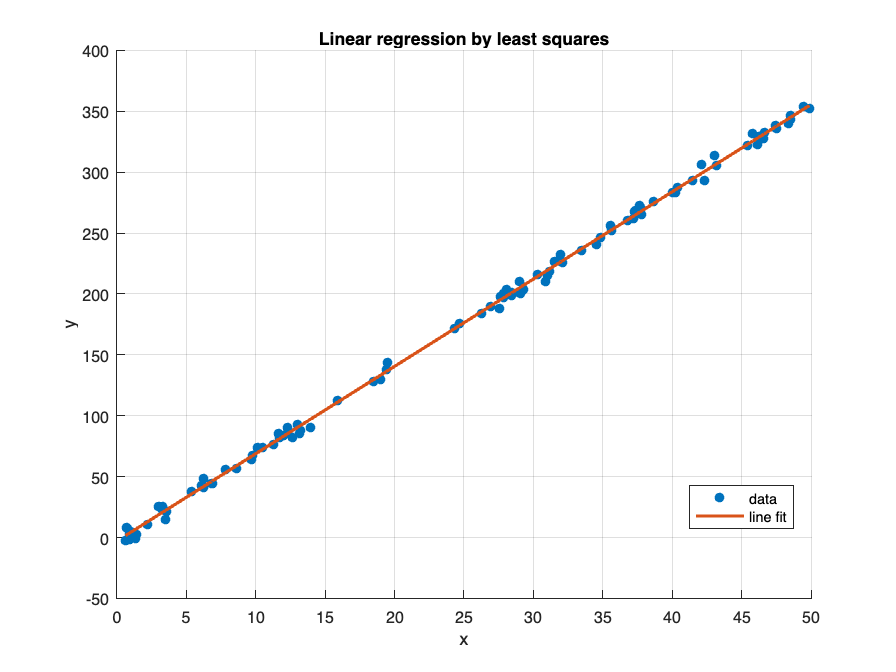


% Plot line fit
figure; scatter(x,y,'filled'); hold on;
[xs, idx] = sort(x);
plot(xs,y_hat(idx),'LineWidth',2);
xlabel('x'); ylabel('y'); legend('data','line fit','Location','best'); grid on;
title('Linear regression by least squares');

## 1.3b)

sigma2 = 12.8;
c0 = 2.8;
y2 = a0 + b0*x + c0*(x.^2)+sigma2*randn(N,1);

Phi2 = [ones(N,1), x, x.^2];
theta2 = Phi2 \ y2;
yhat2 = Phi2*theta2;
theta1 = Phi \ y2;
yhat1 = Phi * theta1;

fprintf('Theta_curve = [a0, b0, c0] = [%.4f, %.4f, %.4f]', theta2)

Theta_curve = [a0, b0, c0] = [-1.9807, 7.3843, 2.7953]

fprintf('Theta_line = [a0, b0] = [%.4f, %.4f]', theta1)

Theta_line = [a0, b0] = [-918.3544, 141.9512]

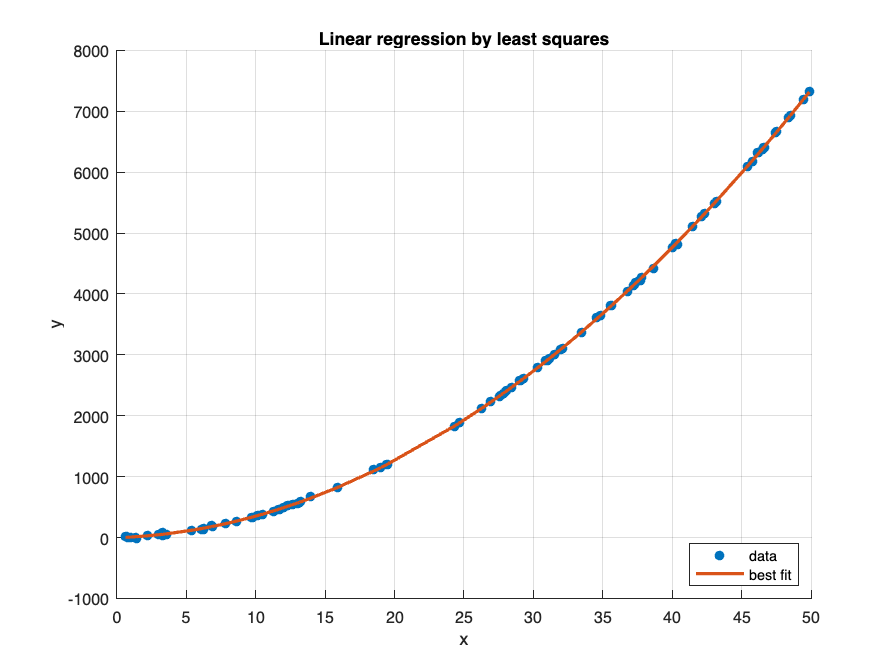


% Plot quadratic fit
figure; scatter(x,y2,'filled'); hold on;
[xs, idx] = sort(x);
plot(xs,yhat2(idx),'LineWidth',2);
xlabel('x'); ylabel('y'); legend('data','best fit','Location','southeast'); grid on;
title('Linear regression by least squares');

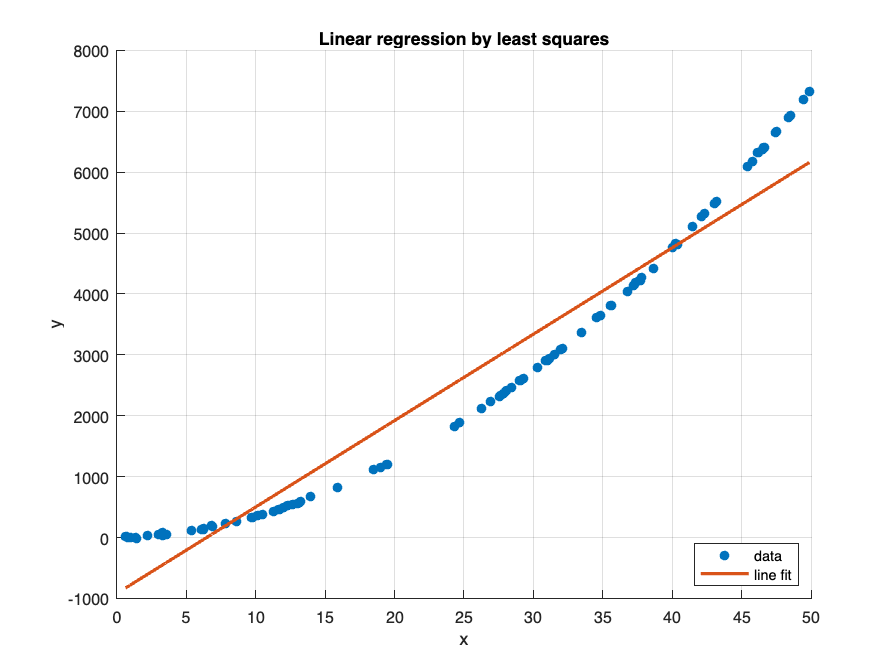


% Plot line fit
figure; scatter(x,y2,'filled'); hold on;
plot(xs,yhat1(idx),'LineWidth',2);
xlabel('x'); ylabel('y'); legend('data','line fit','Location','southeast'); grid on;
title('Linear regression by least squares');


% Residual quadratic and line fit
rmse_quad = rmse(y2, yhat2);
rmse_line = rmse(y2, yhat1);

fprintf('Residual quad = %.4f, Residual line = %.4f', rmse_quad, rmse_line)

Residual quad = 11.0835, Residual line = 550.9230

# 2.3 Identify ARX models

load 'Assignment 2'/input.mat
load 'Assignment 2'/output.mat

N = numel(y);
Ne = floor(0.5*N); % estimation length
Nv = N - Ne; % validation length

ue = u(1:Ne);
ye = y(1:Ne);
uv = u(Ne+1:N);
yv = y(Ne+1:N);

% 12a model

t0a = 3; % number of parameters
T = Ne;
rows = (t0a:T).';
PhiEa = [-ye(rows-1), -ye(rows-2), ue(rows)];
yEa = ye(rows);

% LSE
theta_a = PhiEa \ yEa;

% One step prediction on validation data
T = Nv;
rows = (t0a:T).';
PhiVa = [-yv(rows-1), -yv(rows-2), uv(rows)];
yVa = yv(rows);
yhat_a = PhiVa * theta_a;

ysim_a = zeros(Nv,1);
ysim_a(1:2) = yv(1:2);                   % initial conditions
a1 = theta_a(1); a2 = theta_a(2); b0 = theta_a(3);
for t = t0a:Nv
    ysim_a(t) = -a1*ysim_a(t-1) - a2*ysim_a(t-2) + b0*uv(t);
end

% Errors / RMSE
rmse_pred_a = rmse(yVa, yhat_a);
rmse_sim_a  = rmse(yv(t0a:end), ysim_a(t0a:end));

fprintf('(12a) theta = [a1 a2 b0] = [% .4f % .4f % .4f]\n', theta_a);

(12a) theta = [a1 a2 b0] = [-0.9590  0.3567  0.0688]


fprintf('      RMSE_pred = %.4f,  RMSE_sim = %.4f\n\n', rmse_pred_a, rmse_sim_a);

      RMSE_pred = 1.0587,  RMSE_sim = 1.3948




% 12b model
t0b = 4; % number of parameters
T = Ne;
rows = (t0b:T).';
PhiEb = [-ye(rows-1), -ye(rows-2), ue(rows), ue(rows-1)];
yEb = ye(rows);

% LSE
theta_b = PhiEb \ yEb;

% One step prediction on validation data
T = Nv;
rows = (t0b:T).';
PhiVb = [-yv(rows-1), -yv(rows-2), uv(rows), uv(rows-1)];
yVb = yv(rows);
yhat_b = PhiVb * theta_b;

ysim_b = zeros(Nv,1);
ysim_b(1:2) = yv(1:2);                   % initial conditions
a1 = theta_b(1); a2 = theta_b(2); b0 = theta_b(3); b1 = theta_b(4);
for t = t0b:Nv
    ysim_b(t) = -a1*ysim_b(t-1) - a2*ysim_b(t-2) + b0*uv(t) + b1*uv(t-1);
end

% Errors / RMSE
rmse_pred_b = rmse(yVb, yhat_b);
rmse_sim_b  = rmse(yv(t0b:end), ysim_b(t0b:end));

fprintf('(12b) theta = [a1 a2 b0 b1] = [% .4f % .4f % .4f % .4f]\n', theta_b);

(12b) theta = [a1 a2 b0 b1] = [-0.8923  0.3116  0.0114  0.9946]


fprintf('      RMSE_pred = %.4f,  RMSE_sim = %.4f\n\n', rmse_pred_b, rmse_sim_b);

      RMSE_pred = 0.3169,  RMSE_sim = 0.4216




% 12c model

t0c = 4; % number of parameters
T = Ne;
rows = (t0c:T).';
PhiEc = [-ye(rows-1), -ye(rows-2), -ye(rows-3), ue(rows-1)];
yEc = ye(rows);

% LSE
theta_c = PhiEc \ yEc;

% One step prediction on validation data
T = Nv;
rows = (t0c:T).';
PhiVc = [-yv(rows-1), -yv(rows-2), -yv(rows-3), uv(rows-1)];
yVc = yv(rows);
yhat_c = PhiVc * theta_c;

ysim_c = zeros(Nv,1);
ysim_c(1:4) = yv(1:4); % initial conditions
a1 = theta_c(1); a2 = theta_c(2); a3 = theta_c(3); b1 = theta_c(4);
for t = t0c:Nv
    ysim_c(t) = -a1*ysim_c(t-1) - a2*ysim_c(t-2) - a3*ysim_c(t-3) + b1*uv(t-1);
end

% Errors / RMSE
rmse_pred_c = rmse(yVc, yhat_c);
rmse_sim_c  = rmse(yv(t0c:end), ysim_c(t0c:end));

fprintf('(12c) theta = [a1 a2 a3 b0] = [% .4f % .4f % .4f % .4f]\n', theta_c);

(12c) theta = [a1 a2 a3 b0] = [-1.0000  0.6000 -0.3000  1.0000]


fprintf('      RMSE_pred = %e,  RMSE_sim = %e\n\n', rmse_pred_c, rmse_sim_c);

      RMSE_pred = 2.905594e-16,  RMSE_sim = 4.968786e-16

